# Obstructed and Reflected Paths Using Ray Tracing

Show reflected propagation paths in Chicago using a ray tracing propagation model.

Launch Site Viewer with buildings in Chicago. For more information about the OpenStreetMap® file, see [1].

viewer = siteviewer("Buildings","map.osm");

Create a transmitter site and a receiver site near two different buildings.

tx = txsite("Latitude",12.844727115865297,"Longitude", 77.66375315505691, ...
    "TransmitterFrequency",2.5e9);
show(tx)
rx = rxsite("Latitude",12.844574731540998,"Longitude",77.663239613, ...
    "AntennaHeight",30);
show(rx)

Show the obstruction to the line-of-sight path.

los(tx,rx)

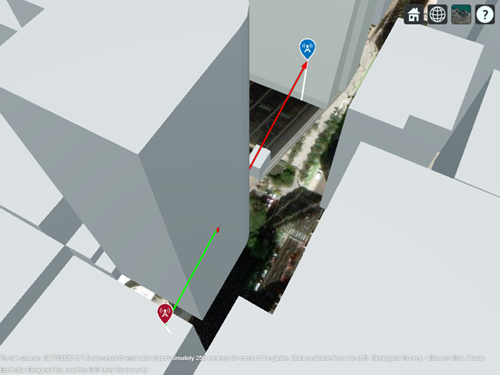

Display propagation paths with reflections. By default, the `raytrace` function uses the SBR method and calculates propagation paths with up to two reflections.

raytrace(tx,rx)

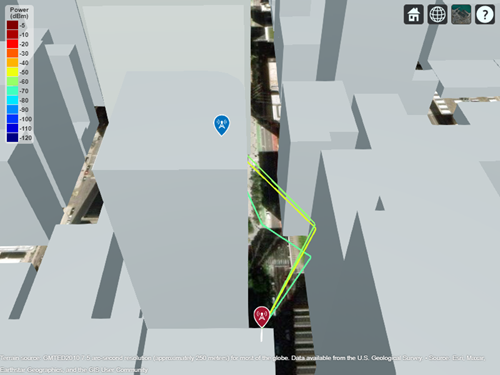

**Appendix**

[1] The OpenStreetMap file is downloaded from [https://www.openstreetmap.org](https://www.openstreetmap.org/), which provides access to crowd-sourced map data all over the world. The data is licensed under the Open Data Commons Open Database License (ODbL), [https://opendatacommons.org/licenses/odbl/](https://opendatacommons.org/licenses/odbl/).

*Copyright 2022-2023 The MathWorks, Inc.*